# **Matisse example for DIGP (probabilisitc cell typing)**

#### **Objective of the notebook**

This notebook is used to run probabilistic cell typing by in situ sequencing (pciseq) (Qian et al. 2020) on the malignant cells. For this, we will first read the location of decoded reads using the toolbox called Matisse (Marco Salas et al. 2021), load the segmentation mask and perform probabilisic cell typing. The same notebook has been used for all the ISS samples present in Liu et al. 2022.

#### **Requirements for running the pipeline**

This notebook requires to have Matisse (Marco Salas et al. 2021) installed, as well as the Image Processing toolbox from Matlab.

### **LOADING DATA**

We create a SPOTS1 file that contains the information of one sample. For this we add to 'image' the path to our dapi of reference. We load as decoded file the path to our csv containing the xy position of the reads. We will indicate the column of the XY position in the function ISS_getspots, toguether with the 'genecolumn', where we will indicate the position of the column containing the gene identity of every decoded spot

SAMP='XT9824_4';
dir='F:\SAMPLES_DECODED\RUN2\';
decoded_file = [dir,SAMP,'\preprocessing\DECODED_',SAMP,'_no_alignment_filt.csv'];
image = [dir,SAMP,'\preprocessing\Stitched2DTiles\Base_1_stitched-1.tif'];    
scale=1; 
ORG43=ISS_getspots(decoded_file,'genecolumn',19,'XYcolumn',[16,17]);
ORG43.image=image;
ORG43.scale=scale;

And then we combine them into a big object (note that if you have added more samples you need to add them here as well)

ALLSPOTS.ORG43=ORG43;

### **Format ALLSSPOTS in good format**

We use 'fill_matisse' to format the ALLSPOTS in the SPOTS object. The SPOTS object is a MatisseMod object, described in MarcoSalas et al. 2020.

SPOTS=fill_matisse(ALLSPOTS);

SPOTS =   matisseMOD with properties:

                                 Graphics: 1
                                 spotname: []
                                 location: []
                                   sample: []
                                   domain: []
                                sample_ID: []
                                   images: []
                                    scale: []
                         expressionmatrix: []
                          expressionnames: []
                              centroidpos: {}
                                 Cellmaps: {}
                               centroidID: {}
            GeneDensity_Genes_of_interest: {}
                    GeneDensity_bandwidth: 300
                     GeneDensity_colormap: [256×3 double]
    OverlayTwoDensities_Genes_of_interest: {}
            OverlayTwoDensities_bandwidth: 300
             OverlayTwoDensities_colormap: [256×3 dou

## **Plotting spots**

We can plot the spots on top of the DAPI to make sure that they match well.

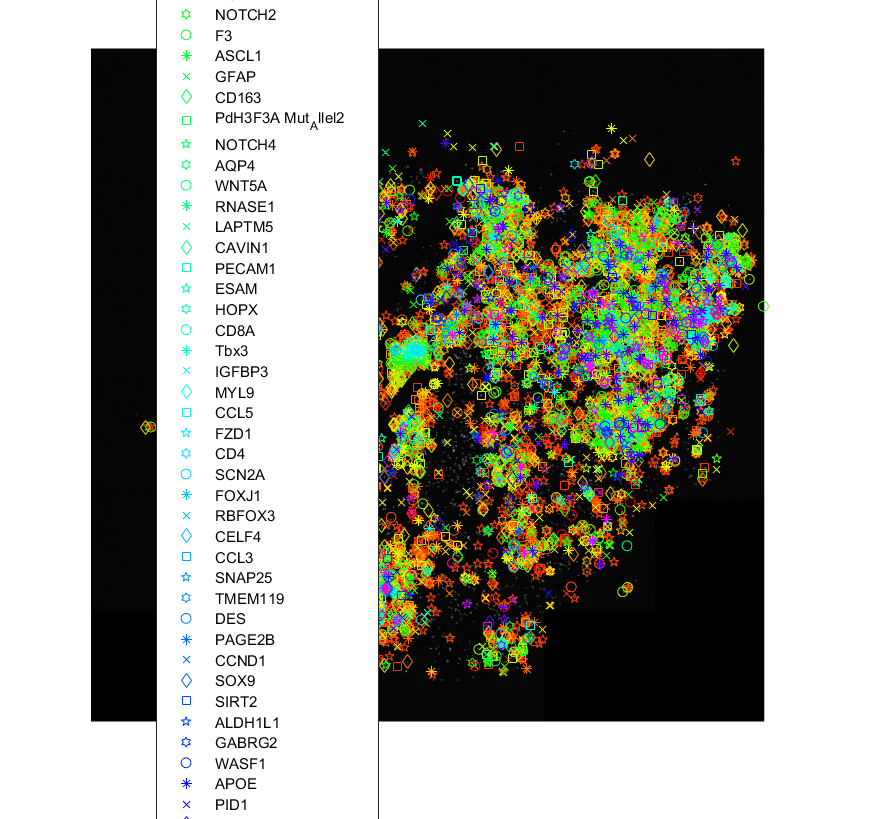

show_spots(SPOTS);

# Assigning reads to individual cells

We then try to assign reads to cells. For this, we first load the segmentation masks, we load the cells and then we use the CellMap in the second function called "define_cells" for creating the cells object.

CORTEX_SPOTS2=SPOTS;
load([dir,SAMP,'\',SAMP,'_CellMap'],"CellMap0")
CELLS=readtable([dir,SAMP,'/',SAMP,'_CELLS_reads_ISS_and_IF.csv']);

We want to only analyze IF+ cells. In this case, we consider as positve cells all the ones with a IF value above 350 (this value is sample-dependent). Therefore, we exclude from the segmentation mask all cells with an IF value lower than our threshold. Then, we incorporate the segmentation map into the Matisse object

CELLS=CELLS(CELLS.mean_IF>350,:); % this values comes from the IF plot
CellMap0(~ismember(CellMap0,unique(CELLS.Cell_ID)))=0;

CORTEX_SPOTS2.Cellmaps{1}=CellMap0;
U2=CellMap0;
blobs = unique(U2);
blobs = blobs(blobs~=0);
size(blobs);
XY=fliplr(vertcat(regionprops(CellMap0).Centroid));

CORTEX_SPOTS2.centroidpos{1}=XY;
CORTEX_SPOTS2.centroidID{1}=blobs;


### **Loading single cell data for comparison with de novo clustering**

 We import a cellxgene matrix containing the gene expression of each signature.

patha="F:\scRNAseq_input\pciseq_dipg_scRNAseq_input.csv";
[SINGLE_CELL]=load_scRNAseq(patha);

SINGLE_CELL.expressionmatrix=SINGLE_CELL.expressionmatrix;



We then run probabilistic cell typining (PCIseq) using:

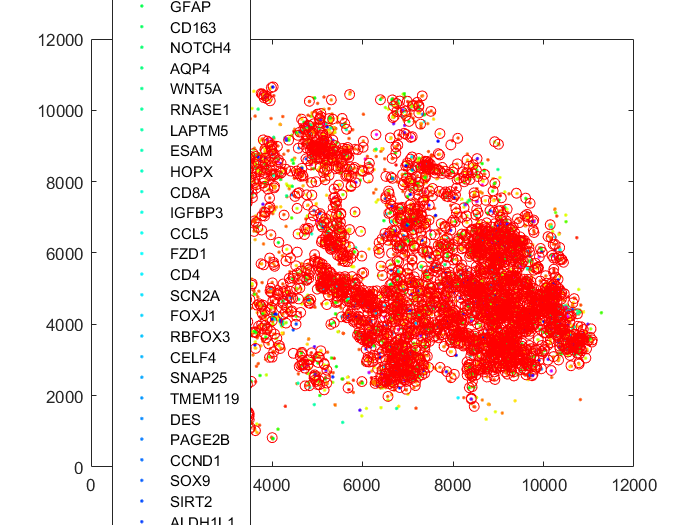

Iteration 1, mean prob change 1.000000
Iteration 2, mean prob change 0.455238
Iteration 3, mean prob change 0.210631
Iteration 4, mean prob change 0.173624
Iteration 5, mean prob change 0.072566
Iteration 6, mean prob change 0.028050
Iteration 7, mean prob change 0.013422


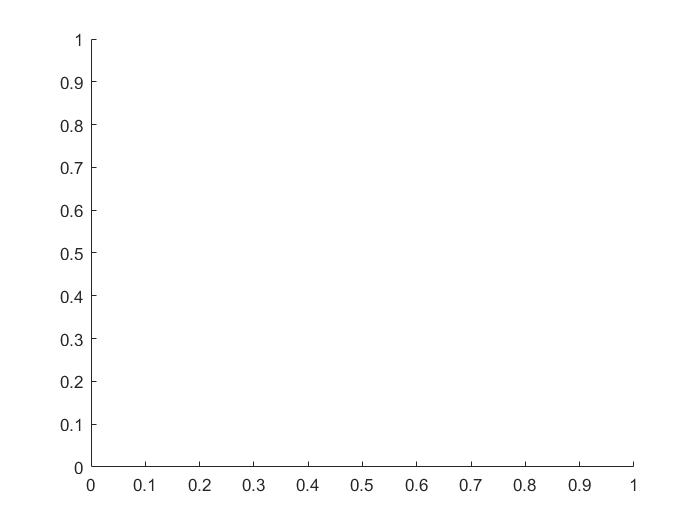

------------------ Cell 134 at 1430,2913: -----------------
Spot 1137: CD74, with prob 0.000000
Spot 1138: CD74, with prob 0.000000
Spot 1139: CD4, with prob 0.000000
Spot 1143: CD74, with prob 0.000000
Spot 1144: MLC1, with prob 0.000000
Spot 1146: LRP5, with prob 0.000000
Spot 1147: CD74, with prob 0.000000
Spot 1148: SEZ6L, with prob 0.000000
Spot 1149: SCG3, with prob 0.000000
Spot 1150: CA10, with prob 0.000000
Spot 1152: NOTCH4, with prob 0.000000
Spot 1153: NOTCH4, with prob 0.000000
Spot 1154: ESAM, with prob 0.000000
Spot 1155: NOTCH4, with prob 0.000000
Spot 1161: EPN2, with prob 0.993901
Spot 1162: CA10, with prob 0.919648
Spot 1163: CA10, with prob 0.611190
Spot 1164: RGR, with prob 0.000000
Spot 1165: GPR17, with prob 0.763101
Spot 1166: GPR17, with prob 0.397822
Spot 1167: ESAM, with prob 0.000000
Spot 1169: ESAM, with prob 0.000000
Spot 1170: NOTCH4, with prob 0.000000
Spot 1171: SCG3, with prob 0.000000
Spot 1180: LNX1, with prob 0.000000
Spot 1191: AGT, with prob 0.000

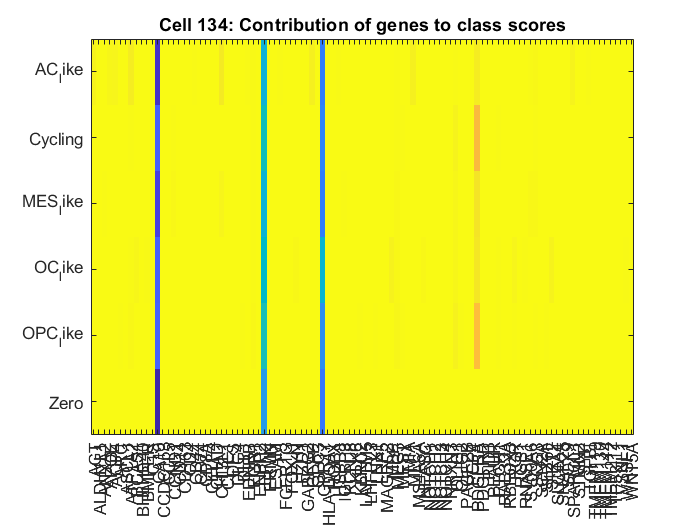

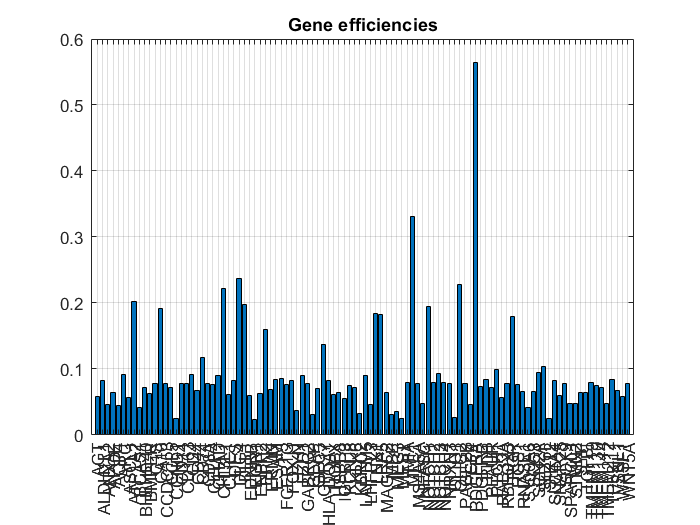

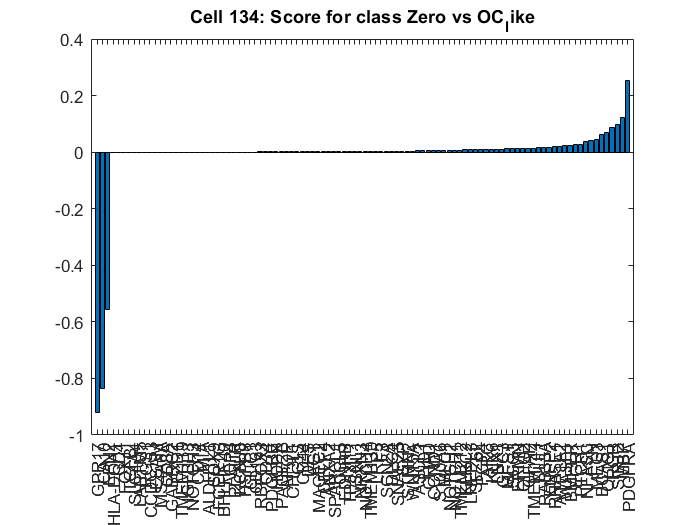

CELLS =   matisseMOD with properties:

                                 Graphics: 1
                                 spotname: {7540×1 cell}
                                 location: [7540×2 double]
                                   sample: {7540×1 cell}
                                   domain: []
                                sample_ID: []
                                   images: {'F:\SAMPLES_DECODED\RUN2\XT9824_4\preprocessing\Stitched2DTiles\Base_1_stitched-1.tif'}
                                    scale: {[1]}
                         expressionmatrix: [7540×102 double]
                          expressionnames: {102×1 cell}
                              centroidpos: {[7540×2 double]}
                                 Cellmaps: {[11289×11295 uint32]}
                               centroidID: {[2747×1 uint32]}
            GeneDensity_Genes_of_interest: {}
                    GeneDensity_bandwidth: 300
     

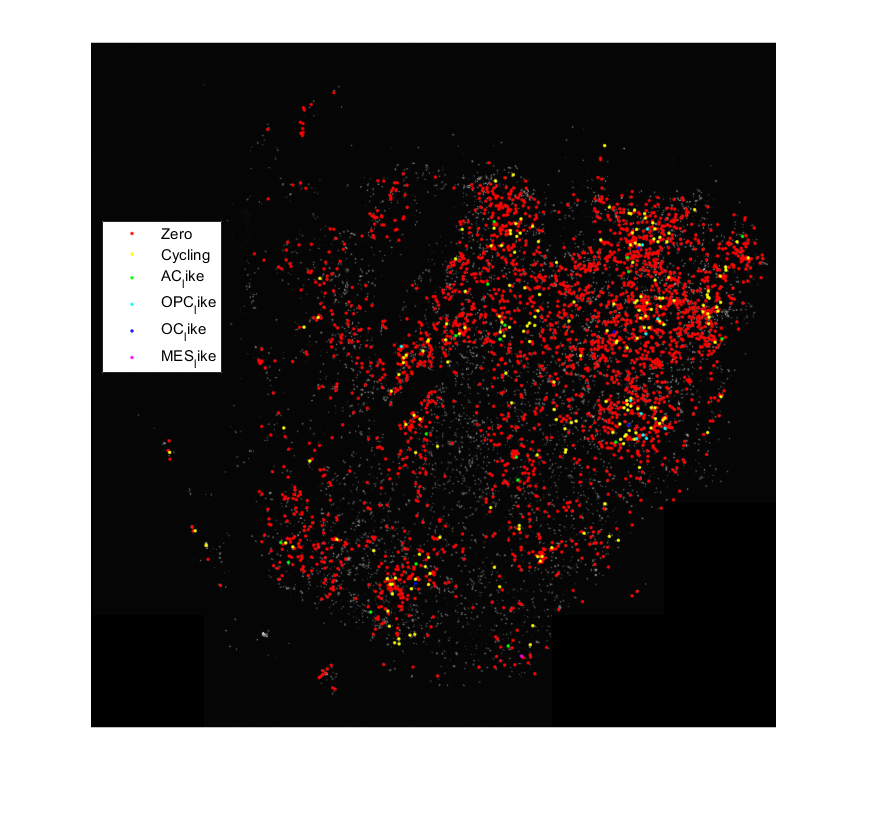

CORTEX_SPOTS2.inefficiency=0.001;
PCISEQ_CELLS=pciseq(CORTEX_SPOTS2,SINGLE_CELL);

#### **Saving the output of pciseq**

We finally save the output of probabilistic cell typing by in situ sequencing. For this, we extract the main outputs, including the expression of each cell detected, the position of every cell and the probobability of every cell to be assigned to every cluster/cell type (or state) in the reference. We save this information in a csv.

TAB=array2table(PCISEQ_CELLS.expressionmatrix);
TAB.Properties.VariableNames=PCISEQ_CELLS.expressionnames;
TAB.name=PCISEQ_CELLS.spotname;
TAB.X=PCISEQ_CELLS.location(:,1);
TAB.Y=PCISEQ_CELLS.location(:,2);

TAB2=array2table(PCISEQ_CELLS.pciseq_probabilities);
TAB2.Properties.VariableNames=PCISEQ_CELLS.pciseq_probabilities_names;

TAB3=horzcat(TAB,TAB2(1:end-1,:));
TAB4=TAB3(~ismember(TAB3.name,{'Zero'}),:);
writetable(TAB4,strcat(dir,SAMP,'\',SAMP,'_pciseq_results.csv'));